## 1.Reading Data

data = readmatrix('ratings.csv');%reading
data = data(:,1:3);%drop out timestemp
data

data =      1     1     4
     1     3     4
     1     6     4
     1    47     5
     1    50     5
     1    70     3
     1   101     5
     1   110     4
     1   151     5
     1   157     5



% remap item ID to 1~n
all_item = unique(data(:,2));
for i=1:size(data,1)
    data(i,2) = find(all_item==data(i,2));
end
data

data =      1     1     4
     1     3     4
     1     6     4
     1    44     5
     1    47     5
     1    63     3
     1    90     5
     1    98     4
     1   125     5
     1   131     5



% devide to train and test data
selected = randperm(size(data,1));
train_number = floor(size(selected,2)*0.8)

train_number =        80668


test_number = size(data,1)-train_number

test_number =        20168


train_data = data(selected(1:train_number),:);
test_data = data(selected(train_number+1:end),:);

## 2.construct interaction matrix

% training data
numberOfUser = size(unique(data(:,1)),1);
numberOfItem = size(unique(data(:,2)),1);
interactionMatrix_train = zeros(numberOfUser,numberOfItem);
for i=1:size(train_data,1)
    if data(i,3)>=3
        interactionMatrix_train(train_data(i,1),train_data(i,2))=1;
    end
end
interactionMatrix_train

interactionMatrix_train =      0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     


% test data
interactionMatrix_test = zeros(numberOfUser,numberOfItem);
for i=1:size(test_data,1)
    if data(i,3)>=3
        interactionMatrix_test(test_data(i,1),test_data(i,2))=1;
    end
end
interactionMatrix_test

interactionMatrix_test =      0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0

## 3.Enbedding user and item vector

input_dimansion = 10;
latent_dimansion = 8;
epoch = 200;
batch_size = 10240;
learning_rate = 0.005;
[User,Item] = nnmf(interactionMatrix_train,input_dimansion);
rows = size(interactionMatrix_train,1);
culs = size(interactionMatrix_train,2);
input = cell(rows*culs,2);
for i=1:rows
    for j=1:culs
        input((i-1)*culs+j,:) = {[User(i,:),Item(:,j)'], interactionMatrix_train(i,j)};
    end
end

factorizationMachine = FM(input_dimansion,latent_dimansion);

loss = factorizationMachine.Vtrain(input,epoch,batch_size,learning_rate);

epoch: 0 , loss = 8.014309e-01
epoch: 1 , loss = 2.517012e-02
epoch: 2 , loss = 1.589319e-02
epoch: 3 , loss = 1.102506e-02
epoch: 4 , loss = 7.656435e-03
epoch: 5 , loss = 1.232340e-02
epoch: 6 , loss = 1.281515e-02
epoch: 7 , loss = 1.178766e-02
epoch: 8 , loss = 1.109467e-02
epoch: 9 , loss = 1.514856e-02
epoch: 10 , loss = 1.350562e-02


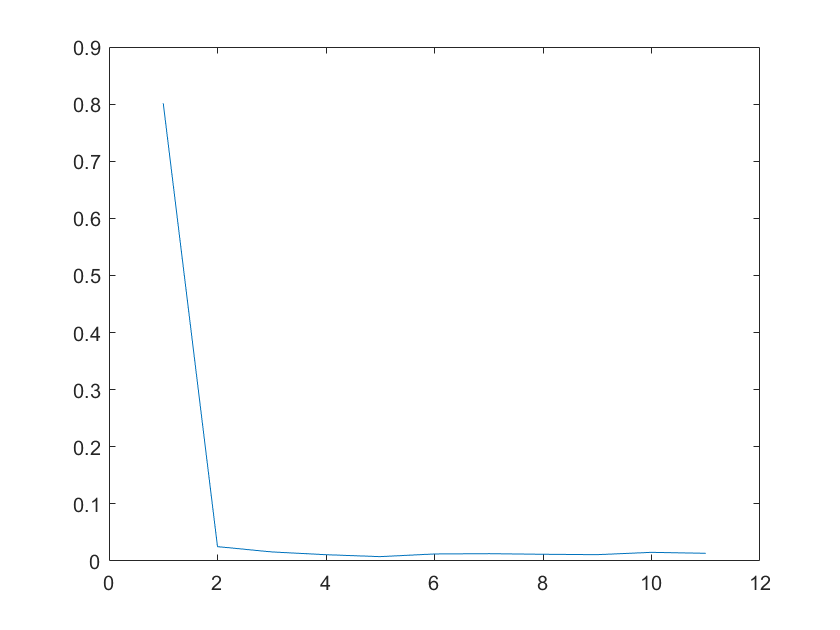

plot(1:11,loss);

% plot(1:201,loss);